# Synthetic Dataset - depth study and DVG quantification

Figuras y estudio para el artículo.

[https://www.mathworks.com/help/matlab/creating_plots/automatic-axes-resize.html](https://www.mathworks.com/help/matlab/creating_plots/automatic-axes-resize.html) 

[https://www.mathworks.com/help/matlab/creating_plots/compare-ways-to-export-save-graphics-plots-from-figures.html](https://www.mathworks.com/help/matlab/creating_plots/compare-ways-to-export-save-graphics-plots-from-figures.html) 

clearvars; format long; %#ok<*AGROW> 
addpath('functions/');
load("ColorsAndOptions.mat","black","blue","green","red","yellow_wa","mint","wesAnderson","blue_wa","purple"); 
fontSize = 10; wideSize = [0 0 15.5 5]; whole_wideSize = [0 0 17 5]; noiseRed_size = [0 0 15.5 2.2];
lineWidth_X = 0.5; noise_lineWidth = 0.65; result_lineWidth = 1.2; colLin_DVGs = wesAnderson(4,:); colLine_noise = red;  
colLine_result = mint; colorDepth = black; depthDot_size = 0.5; alpha_result = 0.95; alpha_outNoise = 0.5; alphaNoiseLines = 0.925;

## 1. Dataset generation

Load and synthetic data

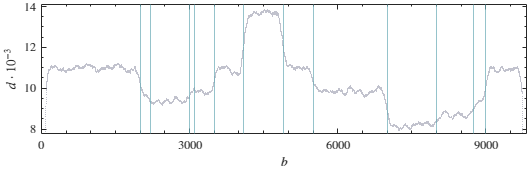

[base, depth] = DSdepth_read("Data/SDgen_depth.mapped.txt"); 
[BP, RI, p_teo, DVGType, DScomposition] = sintheticDScoordinates_output("Data/SDgen_depth_composition.csv"); 
BPRI = sort([BP' RI']); lengthTuMV = 9832;
X = [1 BPRI lengthTuMV];

TXind = unique([X X(2:(end-1))-1 X(2:(end-1))+1]);

figure; tiledlayout(1,1,"TileSpacing","tight","Padding","tight") 
nexttile; hold on 
scatter(base,depth,depthDot_size,'o','filled','CData',colorDepth)
for i = 1:length(BP) 
    xline(BP(i),'-','Color',colLin_DVGs,'LineWidth',lineWidth_X);
    xline(RI(i),'-','Color',colLin_DVGs,'LineWidth',lineWidth_X);
end
xlabel('$b$','Interpreter','latex'); 
ylabel('$d \cdot 10^{-3}$','Interpreter','latex'); 
xlim([0 lengthTuMV]); xticks([0 3000 6000 9000]); 
ylim([7800 14100]); yticks([8 10 12 14].*10^3); yticklabels({'8','10','12','14'})
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on
set(gcf,'renderer','Painters','Units','centimeters','Position',wideSize); 
exportgraphics(gcf,'Figures/syntheticDepthProfile.pdf','ContentType','vector')

## 2. Noise reduction

Set algorithm parameters

interval = 0.8;
quantileNoise = 5;

### (i) Obtain the median ($\bar{d_i }$) of the interval and $\tilde{d_i }$

medianDepth = zeros(1,length(X)-1); delta_medianDepth = []; bases_medianDepth = [];
for i = 1:length(X)-1
    Centroid = round(X(i)+1/2*(X(i+1)-X(i)));
    NData = round((X(i+1)-X(i))*interval/2);
    selectedBases = (Centroid-NData):1:(Centroid+NData);   
    medianDepth(i) = median(depth(ismember(base,selectedBases)));
    delta_medianDepth = [delta_medianDepth ...
        ((depth(ismember(base,selectedBases))-medianDepth(i))./medianDepth(i))'];
    bases_medianDepth = [bases_medianDepth base(ismember(base,selectedBases))'];
    clear Centroid NData selectedBases
end; clear i

### (ii) Compute noise level

Deltas = sort(delta_medianDepth);
Qnoise = quantile(Deltas,1-quantileNoise/100); Q50 = quantile(Deltas,0.50);
upLim = Qnoise; lowLim = 2*Q50-Qnoise; clear Qnoise
noiseLimit = (abs(upLim)+abs(lowLim))./2; 
[upperLim,lowerLim,median_per_base] = deal([]);
for i = 1:length(medianDepth)  
    lowerLim = [lowerLim ones(1,X(i+1)-X(i)).*(medianDepth(i)*(1+lowLim))]; 
    upperLim = [upperLim ones(1,X(i+1)-X(i)).*(medianDepth(i)*(1+upLim))];
    median_per_base = [median_per_base ones(1,X(i+1)-X(i)).*medianDepth(i)];
end
lowerLim(lengthTuMV) = (medianDepth(i)*(1+upLim));
upperLim(lengthTuMV) = (medianDepth(i)*(1+lowLim));
median_per_base(lengthTuMV) = medianDepth(i);
d_ast = (depth-median_per_base')./median_per_base';

### (iii) Select bases inside noise limits

[bases_inNoise, bases_outNoise] = deal([]);
for i = 1:length(depth)
    if depth(i) > lowerLim(i) && depth(i) < upperLim(i)
        bases_inNoise= [bases_inNoise base(i)];
    else
        bases_outNoise= [bases_outNoise base(i)];
    end
end

### (iv) Plot the results of the noise study

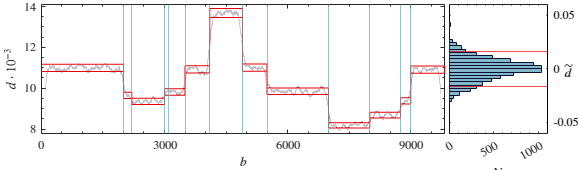

figure; tiledlayout(1,5,"TileSpacing","tight",'Padding','tight'); 
nexttile([1 4]); hold on
scatter(base(bases_outNoise),depth(bases_outNoise),depthDot_size,'o','filled','CData',colorDepth,'MarkerFaceAlpha',alpha_outNoise,'MarkerEdgeAlpha',alpha_outNoise)
scatter(base(bases_inNoise),depth(bases_inNoise),depthDot_size,'o','filled','CData',colorDepth)
plot(base,lowerLim,'Color',[colLine_noise alphaNoiseLines],'LineWidth',noise_lineWidth); 
plot(base,upperLim,'Color',[colLine_noise alphaNoiseLines],'LineWidth',noise_lineWidth);
for i = 1:length(BP) 
    xline(BP(i),'-','Color',colLin_DVGs,'LineWidth',lineWidth_X);
    xline(RI(i),'-','Color',colLin_DVGs,'LineWidth',lineWidth_X);
end
xlim([0 lengthTuMV]); xticks([0 3000 6000 9000]); 
ylim([7800 14100]); yticks([8 10 12 14].*10^3); yticklabels({'8','10','12','14'})
xlabel('$b$','Interpreter','latex'); 
ylabel('$d \cdot 10^{-3}$','Interpreter','latex'); 
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on

nexttile; hold on
histogram(delta_medianDepth,100,"FaceColor",blue_wa,"EdgeColor",black,'Orientation','horizontal')
yline(lowLim,'-','Color',colLine_noise,'LineWidth',noise_lineWidth);
yline(upLim,'-','Color',colLine_noise,'LineWidth',noise_lineWidth); 
xlabel('N','Interpreter',"latex"); 
ylim([-0.06 0.06]); yticks([-0.05 0 0.05]); yticklabels('')
xlim([0 1100]); xticks([0 500 1000]);
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on
yyaxis right; ylim([-0.06 0.06]); yticks([-0.05 0 0.05]);
ylabel('$\tilde{d}$','Interpreter',"latex",'HorizontalAlignment','right','VerticalAlignment','middle','Rotation',0,'Position',[1400 0 -1]); 
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
set(gcf,'renderer','Painters','Units','centimeters','Position',whole_wideSize); 
exportgraphics(gcf,'Figures/NoiseReduction_wHistogram.pdf','ContentType','vector')

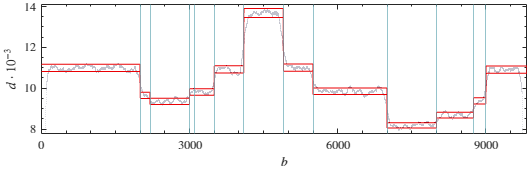

figure; tiledlayout(1,1,"TileSpacing","tight",'Padding','tight'); 
nexttile; hold on
scatter(base(bases_outNoise),depth(bases_outNoise),depthDot_size,'o','filled','CData',colorDepth,'MarkerFaceAlpha',alpha_outNoise,'MarkerEdgeAlpha',alpha_outNoise)
scatter(base(bases_inNoise),depth(bases_inNoise),depthDot_size,'o','filled','CData',colorDepth)
plot(base,lowerLim,'Color',[colLine_noise alphaNoiseLines],'LineWidth',noise_lineWidth); 
plot(base,upperLim,'Color',[colLine_noise alphaNoiseLines],'LineWidth',noise_lineWidth);
for i = 1:length(BP)    
    xline(BP(i),'-','Color',colLin_DVGs,'LineWidth',lineWidth_X);
    xline(RI(i),'-','Color',colLin_DVGs,'LineWidth',lineWidth_X);
end
xlim([0 lengthTuMV]); xticks([0 3000 6000 9000]); xlabel('$b$','Interpreter','latex');  %xticklabels('')
ylim([7800 14100]); yticks([8 10 12 14].*10^3); yticklabels({'8','10','12','14'})
ylabel('$d \cdot 10^{-3}$','Interpreter','latex');
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on
set(gcf,'renderer','Painters','Units','centimeters','Position',wideSize); 
exportgraphics(gcf,'Figures/NoiseReduction_top.pdf','ContentType','vector')

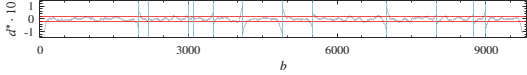

figure; tiledlayout(1,1,"TileSpacing","tight",'Padding','tight'); 
nexttile; hold on
scatter(base(bases_outNoise),d_ast(bases_outNoise),depthDot_size,'o','filled','CData',colorDepth,'MarkerFaceAlpha',alpha_outNoise,'MarkerEdgeAlpha',alpha_outNoise)
scatter(base(bases_inNoise),d_ast(bases_inNoise),depthDot_size,'o','filled','CData',colorDepth)
yline(lowLim,'-','Color',colLine_noise,'LineWidth',noise_lineWidth);
yline(upLim,'-','Color',colLine_noise,'LineWidth',noise_lineWidth);
for i = 1:length(BP)
    xline(BP(i),'-','Color',colLin_DVGs,'LineWidth',lineWidth_X);
    xline(RI(i),'-','Color',colLin_DVGs,'LineWidth',lineWidth_X);
end
xlim([0 lengthTuMV]); xticks([0 3000 6000 9000]); 
xlabel('$b$','Interpreter','latex'); 
ylim([-0.15 0.15]); yticks([-0.1 0 0.1]); yticklabels({'-1','0','1'})
ylabel('$d^\ast \cdot 10$','Interpreter','latex'); 
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on
set(gcf,'renderer','Painters','Units','centimeters','Position',noiseRed_size); 
exportgraphics(gcf,'Figures/NoiseReduction_bottom.pdf','ContentType','vector')

## 3. DVGM computation

DVGM = DVG_Matrix(lengthTuMV,BP,RI,DVGType);

## 4. DVG quantification

[n,std,~] = lscov(DVGM(:,bases_inNoise)',depth(bases_inNoise));
prop = n./sum(n); err_prop = std./sum(n);
Results = DScomposition(:,[3 1 2 4]); Results = Results([end 1:(end-1)],:);
Results.estim_prop = prop;
Results.err_estim_prop = err_prop;
Results.rel_err = abs(Results.proportion - Results.estim_prop)./Results.proportion*100;
disp(Results)

         DVG_type           BP      RI     proportion        estim_prop           err_estim_prop            rel_err     
    ___________________    ____    ____    __________    __________________    ____________________    _________________

    "WT"                    NaN     NaN        0.3        0.295307155200634    0.000643649788476495     1.56428159978855
    "Deletion_forward"     2000    3000        0.1        0.100834894175619    0.000385008112279034    0.834894175619202
    "Deletion_forward"     7000    9000       0.15        0.151477618886472    0.000339275096271512    0.985079257647921
    "3cb/sb"               8000    8750       0.05       0.0498207827514987    0.000201191240051608    0.358434497002624
    "5cb/sb"               3100    

## 5. Depth profile reconstruction

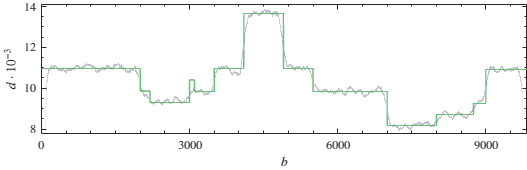

figure; tiledlayout(1,1,"TileSpacing","tight","Padding","tight") 
nexttile; hold on
scatter(base(bases_outNoise),depth(bases_outNoise),depthDot_size,'o','filled','CData',colorDepth,'MarkerFaceAlpha',alpha_outNoise,'MarkerEdgeAlpha',alpha_outNoise)
scatter(base(bases_inNoise),depth(bases_inNoise),depthDot_size,'o','filled','CData',colorDepth)
plot(base,DVGM'*n,'Color',[mint alpha_result],'LineWidth',result_lineWidth)
xlabel('$b$','Interpreter','latex'); 
ylabel('$d \cdot 10^{-3}$','Interpreter','latex'); 
xlim([0 lengthTuMV]); xticks([0 3000 6000 9000]); 
ylim([7800 14100]); yticks([8 10 12 14].*10^3); yticklabels({'8','10','12','14'})
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on
set(gcf,'renderer','Painters','Units','centimeters','Position',wideSize);
exportgraphics(gcf,'Figures/syntheticDataset_result.pdf','ContentType','vector')